# SNW_VFI_PARAM Small Solution Analysis

This is the example vignette for function: [**snw_vfi_main**](https://github.com/FanWangEcon/PrjOptiSNW/blob/master/PrjOptiSNW/svalpol/snw_vfi_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for policy function fully iteratively using matlab minimizer. Small Solution Analysis.

## Test SNW_VFI_MAIN Defaults Small

Call the function with defaults.

mp_param = snw_mp_param('default_small');
[V_VFI,ap_VFI,cons_VFI,mp_valpol_more] = snw_vfi_main(mp_param);

SNW_VFI_MAIN: Finished Age Group:18 of 18
SNW_VFI_MAIN: Finished Age Group:17 of 18
SNW_VFI_MAIN: Finished Age Group:16 of 18
SNW_VFI_MAIN: Finished Age Group:15 of 18
SNW_VFI_MAIN: Finished Age Group:14 of 18
SNW_VFI_MAIN: Finished Age Group:13 of 18
SNW_VFI_MAIN: Finished Age Group:12 of 18
SNW_VFI_MAIN: Finished Age Group:11 of 18
SNW_VFI_MAIN: Finished Age Group:10 of 18
SNW_VFI_MAIN: Finished Age Group:9 of 18
SNW_VFI_MAIN: Finished Age Group:8 of 18
SNW_VFI_MAIN: Finished Age Group:7 of 18
SNW_VFI_MAIN: Finished Age Group:6 of 18
SNW_VFI_MAIN: Finished Age Group:5 of 18
SNW_VFI_MAIN: Finished Age Group:4 of 18
SNW_VFI_MAIN: Finished Age Group:3 of 18
SNW_VFI_MAIN: Finished Age Group:2 of 18
SNW_VFI_MAIN: Finished Age Group:1 of 18
Elapsed time is 417.317296 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=default_small;SNW_MP_CONTROL=default_base


## Small Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 22:5:97, 100];
agrid = mp_param('agrid')';
eta_H_grid = mp_param('eta_H_grid')';
eta_S_grid = mp_param('eta_S_grid')';
ar_st_eta_HS_grid = string(cellstr([num2str(eta_H_grid', 'hz=%3.2f;'), num2str(eta_S_grid', 'wz=%3.2f')]));
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'eta', 1:length(eta_H_grid)});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Savings and Shocks

First, analyze Savings Levels and Shocks, Aggregate Over All Others, and do various other calculations.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('cl_st_xtitle') = {'Savings States, a'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log

#### MEAN(VAL(A,Z)), MEAN(AP(A,Z)), MEAN(C(A,Z))

Tabulate value and policies along savings and shocks:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(A,Z))", V_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5
    _____    _________    __________    __________    __________    __________    __________

      1              0      -7.2503       -5.2835       -3.7134       -2.4567      -1.4584  
      2      0.0097656      -7.1324       -5.1969       -3.6417       -2.3926      -1.3985  
      3       0.078125      -6.4761       -4.7107       -3.2467       -2.0451      -1.0782  
      4        0.26367      -5.3285       -3.8496       -2.5707       -1.4781      -0.5735  
      5          0.625       -3.966       -2.8108       -1.7735      -0.84485       -0.042  
      6         1.2207       -2.597       -1.7598      -0.953

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(A,Z))", ap_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5
    _____    _________    __________    __________    __________    __________    __________

      1              0    0.0031716      0.018272       0.06218      0.16375        0.3592  
      2      0.0097656    0.0042196      0.020157      0.065446       0.1682       0.36427  
      3       0.078125     0.019501      0.043246      0.094811      0.20238       0.40176  
      4        0.26367      0.12027       0.14626       0.20802      0.31671       0.51983  
      5          0.625      0.37099       0.40364       0.45361      0.57742       0.77043  
      6         1.2207      0.81325         0.855       0.9010

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(A,Z))", cons_VFI, true, ["mean"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group     savings     mean_eta_1    mean_eta_2    mean_eta_3    mean_eta_4    mean_eta_5
    _____    _________    __________    __________    __________    __________    __________

      1              0     0.47551       0.59993       0.77031        1.0006        1.3228  
      2      0.0097656     0.48592       0.60947       0.77846        1.0076        1.3291  
      3       0.078125      0.5508        0.6664       0.82898        1.0532        1.3714  
      4        0.26367     0.66751       0.78048       0.93255        1.1554        1.4697  
      5          0.625     0.83992       0.94558        1.1089        1.3162        1.6403  
      6         1.2207      1.0943        1.1901        1.3565 

Graph Mean Values:

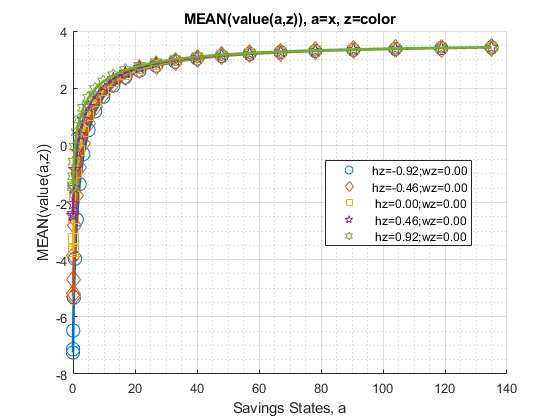

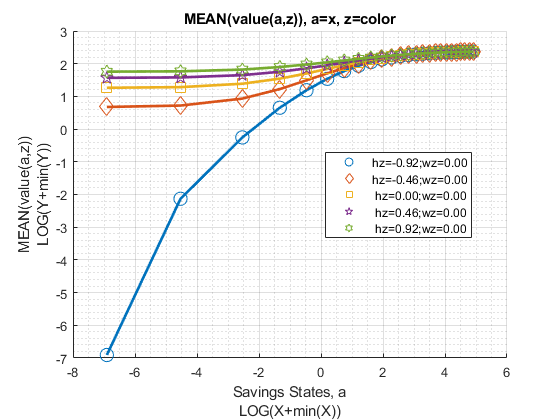

mp_support_graph('cl_st_graph_title') = {'MEAN(value(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(a,z))'};
ff_graph_grid((tb_az_v{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Savings Choices:

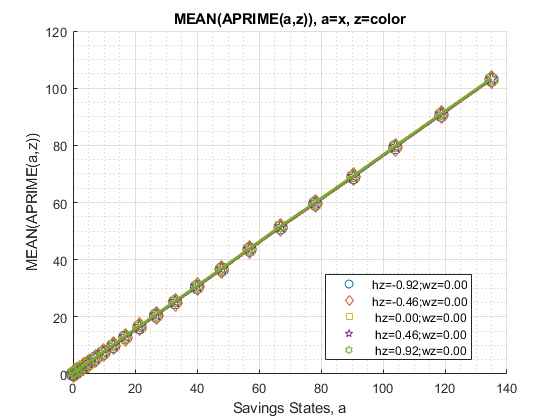

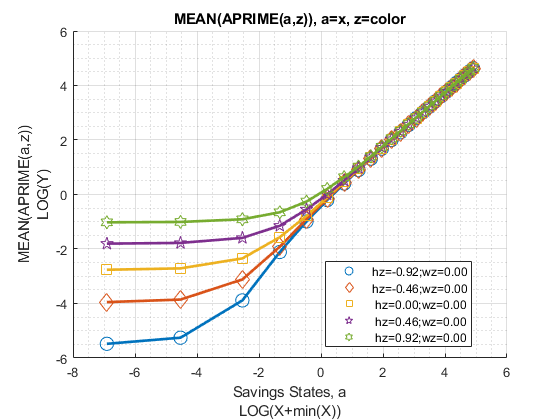

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(a,z))'};
ff_graph_grid((tb_az_ap{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

Graph Mean Consumption:

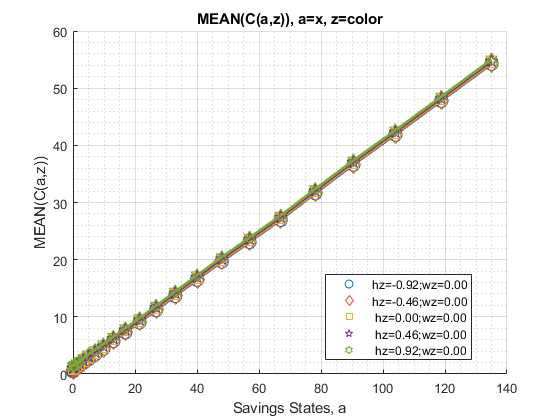

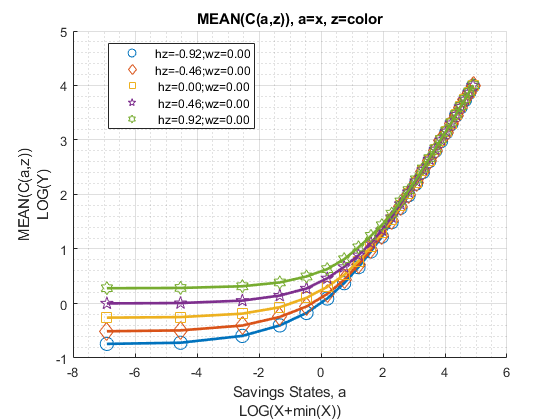

mp_support_graph('cl_st_graph_title') = {'MEAN(C(a,z)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(a,z))'};
ff_graph_grid((tb_az_c{1:end, 3:end})', ar_st_eta_HS_grid, agrid, mp_support_graph);

## Analyze Kids and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};

#### MEAN(VAL(KM,J)), MEAN(AP(KM,J)), MEAN(C(KM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(KM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ___________

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(KM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ___________

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(KM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(KM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ____    _____    ___________    ___________    ___________    ___________    ___________    ___________    ___________

Graph Mean Values:

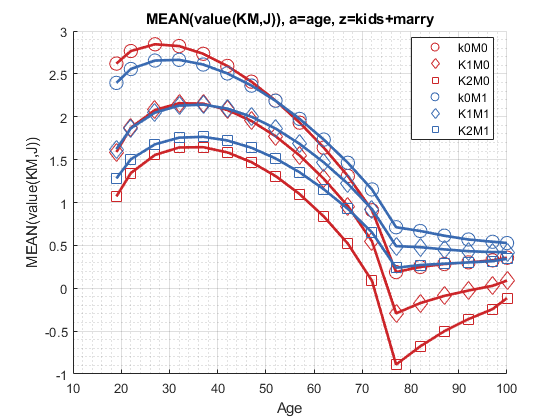

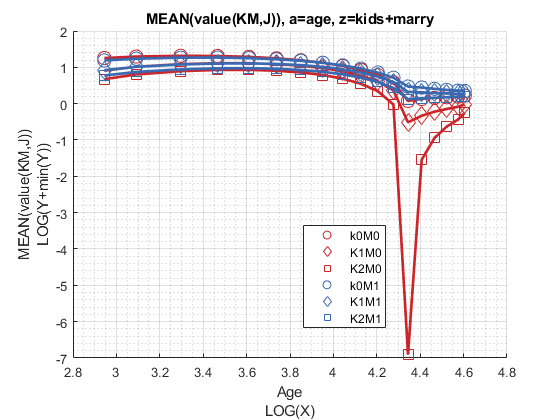

mp_support_graph('cl_st_graph_title') = {'MEAN(value(KM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(KM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

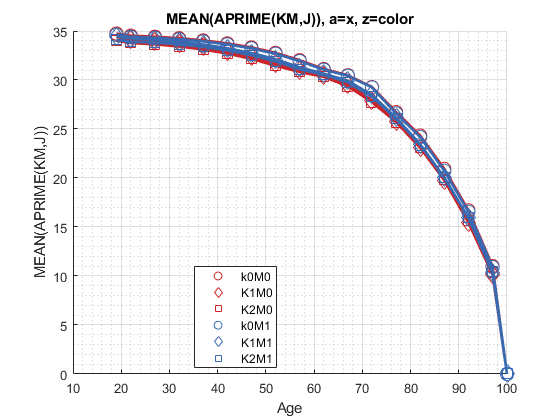

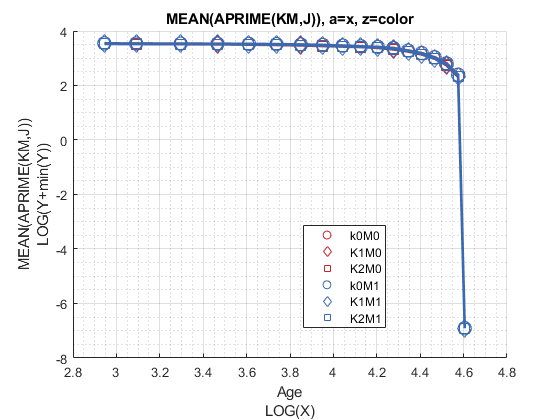

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(KM,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

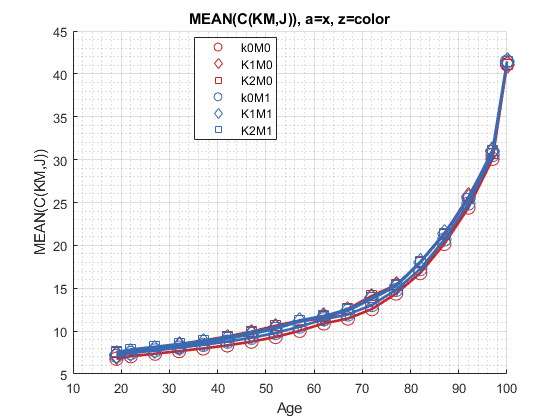

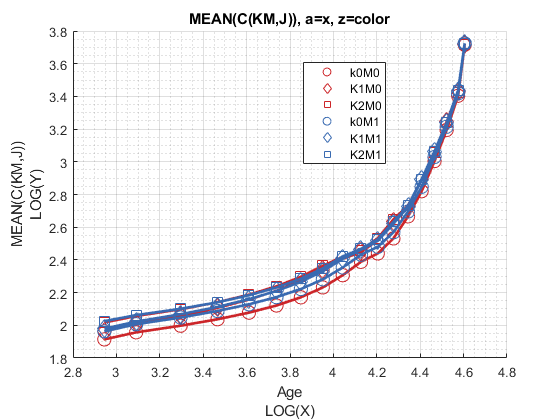

mp_support_graph('cl_st_graph_title') = {'MEAN(C(KM,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(KM,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Education and Marriage and Age

Aggregating over education, savings, and shocks, what are the differential effects of Marriage and Age.

% Generate some Data
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
ar_row_grid = ["E0M0", "E1M0", "E0M1", "E1M1"];
mp_support_graph('cl_st_xtitle') = {'Age'};
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = true; % do not log
mp_support_graph('st_rounding') = '6.2f'; % format shock legend
mp_support_graph('cl_scatter_shapes') = {'*', 'p', '*','p' };
mp_support_graph('cl_colors') = {'red', 'red', 'blue', 'blue'};

#### MEAN(VAL(EKM,J)), MEAN(AP(EKM,J)), MEAN(C(EKM,J))

Tabulate value and policies:

% Set
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,4,5];
% Value Function
tb_az_v = ff_summ_nd_array("MEAN(VAL(EKM,J))", V_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(VAL(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ___________

% Aprime Choice
tb_az_ap = ff_summ_nd_array("MEAN(AP(EKM,J))", ap_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(AP(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ___________

% Consumption Choices
tb_az_c = ff_summ_nd_array("MEAN(C(EKM,J))", cons_VFI, true, ["mean"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  MEAN(C(EKM,J))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    edu    marry    mean_age_19    mean_age_22    mean_age_27    mean_age_32    mean_age_37    mean_age_42    mean_age_47    mean_age_52    mean_age_57    mean_age_62    mean_age_67    mean_age_72    mean_age_77    mean_age_82    mean_age_87    mean_age_92    mean_age_97    mean_age_100
    _____    ___    _____    ___________    ___________    ___________    ___________    ___________    ___________    ___________

Graph Mean Values:

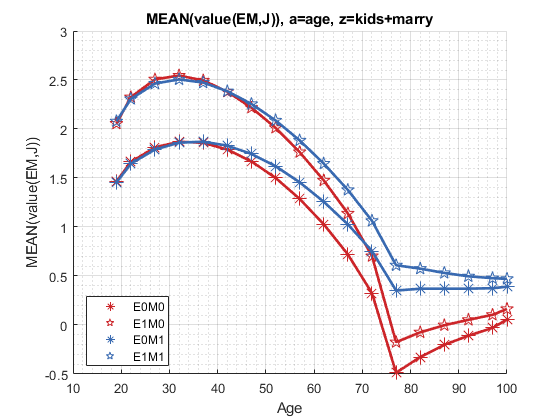

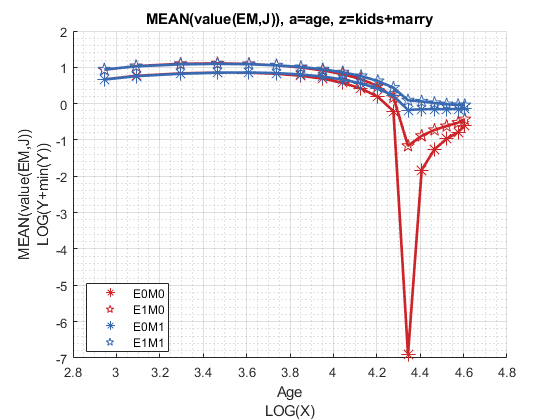

mp_support_graph('cl_st_graph_title') = {'MEAN(value(EM,J)), a=age, z=kids+marry'};
mp_support_graph('cl_st_ytitle') = {'MEAN(value(EM,J))'};
ff_graph_grid((tb_az_v{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Savings Choices:

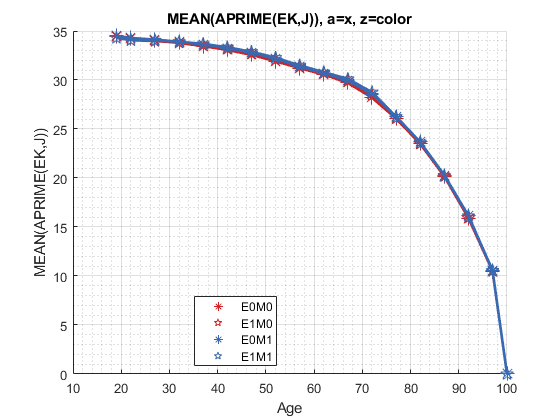

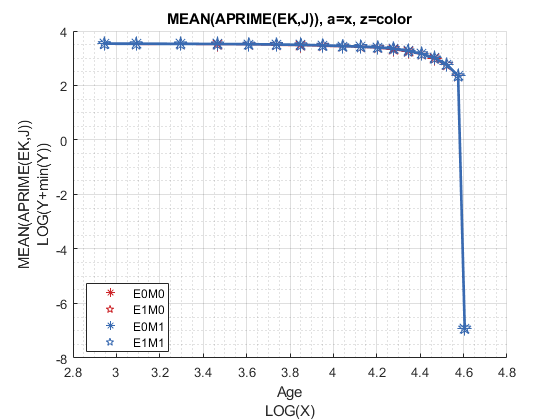

mp_support_graph('cl_st_graph_title') = {'MEAN(APRIME(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(APRIME(EK,J))'};
ff_graph_grid((tb_az_ap{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

Graph Mean Consumption:

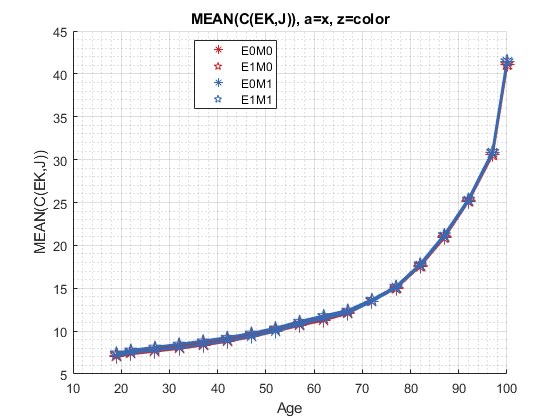

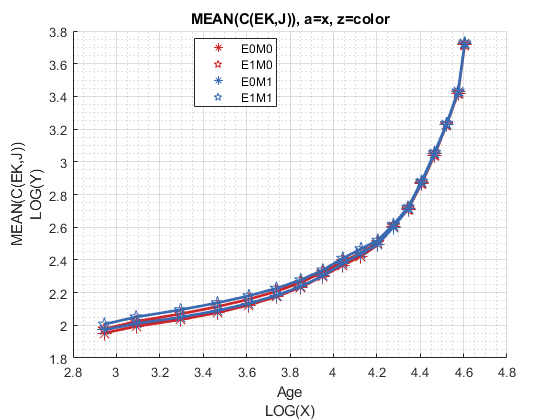

mp_support_graph('cl_st_graph_title') = {'MEAN(C(EK,J)), a=x, z=color'};
mp_support_graph('cl_st_ytitle') = {'MEAN(C(EK,J))'};
ff_graph_grid((tb_az_c{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);